% (x*cos(y)-y*sin(y))*dy+(x*sin(y)+y*cos(y))*dx=0

clear
% 1)
% y'==-(x*sin(y)+y*cos(y))/(x*cos(y)-y*sin(y))
syms x y(x) C
eqn=diff(y(x))==-(x*sin(y)+y*cos(y))/(x*cos(y)-y*sin(y))

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=-\frac{x\,\sin\left(y\left(x\right)\right)+\cos\left(y\left(x\right)\right)\,y\left(x\right)}{x\,\cos\left(y\left(x\right)\right)-\sin\left(y\left(x\right)\right)\,y\left(x\right)}$$

ySol=dsolve(eqn)

$$ySol = \mathrm{solve}\left(C_{28}-{\mathrm{e}}^{x}\,\left(y\,\cos\left(y\right)-\sin\left(y\right)+x\,\sin\left(y\right)\right),y\right)$$

% solve(y*cos(y) - sin(y) + x*sin(y) == C17*exp(-x), y)
eq1= y*cos(y) - sin(y) + x*sin(y) - C*exp(-x)

$$eq1(x) = x\,\sin\left(y\left(x\right)\right)-\sin\left(y\left(x\right)\right)+\cos\left(y\left(x\right)\right)\,y\left(x\right)-C\,{\mathrm{e}}^{-x}$$

eq1=simplify(eq1*exp(x))

$$eq1(x) = x\,\sin\left(y\left(x\right)\right)\,{\mathrm{e}}^{x}-\sin\left(y\left(x\right)\right)\,{\mathrm{e}}^{x}-C+\cos\left(y\left(x\right)\right)\,{\mathrm{e}}^{x}\,y\left(x\right)$$


% 2)
syms x y dx dy C
eq1=(x*cos(y)-y*sin(y))*dy+(x*sin(y)+y*cos(y))*dx

$$eq1 = \mathrm{dx}\,\left(y\,\cos\left(y\right)+x\,\sin\left(y\right)\right)+\mathrm{dy}\,\left(x\,\cos\left(y\right)-y\,\sin\left(y\right)\right)$$

cfs=coeffs(eq1,[dy dx])

$$cfs = \left(\begin{array}{cc} y\,\cos\left(y\right)+x\,\sin\left(y\right) & x\,\cos\left(y\right)-y\,\sin\left(y\right) \end{array}\right)$$

P=cfs(1), Q=cfs(2)

$$P = y\,\cos\left(y\right)+x\,\sin\left(y\right)$$

$$Q = x\,\cos\left(y\right)-y\,\sin\left(y\right)$$

f=simplify(diff(P,y)-diff(Q,x))

$$f = x\,\cos\left(y\right)-y\,\sin\left(y\right)$$

% dPy /= dQx

eq2=f/Q

$$eq2 = 1$$

% 1
mu=exp(int(eq2,x))

$$mu = {\mathrm{e}}^{x}$$

% exp(x)
P1=P*mu, Q1=Q*mu

$$P1 = {\mathrm{e}}^{x}\,\left(y\,\cos\left(y\right)+x\,\sin\left(y\right)\right)$$

$$Q1 = {\mathrm{e}}^{x}\,\left(x\,\cos\left(y\right)-y\,\sin\left(y\right)\right)$$

% exp(x)*(y*cos(y) + x*sin(y))

f1=simplify(diff(P1,y)-diff(Q1,x))

$$f1 = 0$$

% dP1y==dQ1x

% U(x,y)
% dUy=Q1, dUx=P1
syms C(x)
U=int(Q1,y)+C(x)

$$U = C\left(x\right)+{\mathrm{e}}^{x}\,\sin\left(y\right)\,\left(x-1\right)+y\,{\mathrm{e}}^{x}\,\cos\left(y\right)$$

% C(x) + exp(x)*sin(y)*(x - 1) + y*exp(x)*cos(y)
simplify(diff(U,x)-P1)

$$ans = \frac{\partial }{\partial x}C\left(x\right)$$

% diff(C(x), x) = 0 => C(x)=C
% exp(x)*sin(y)*(x - 1) + y*exp(x)*cos(y) = C
% exp(x)*(x*sin(y)+y*cos(y)-sin(y))=C
U=exp(x)*(x*sin(y)+y*cos(y)-sin(y))

$$U = {\mathrm{e}}^{x}\,\left(y\,\cos\left(y\right)-\sin\left(y\right)+x\,\sin\left(y\right)\right)$$

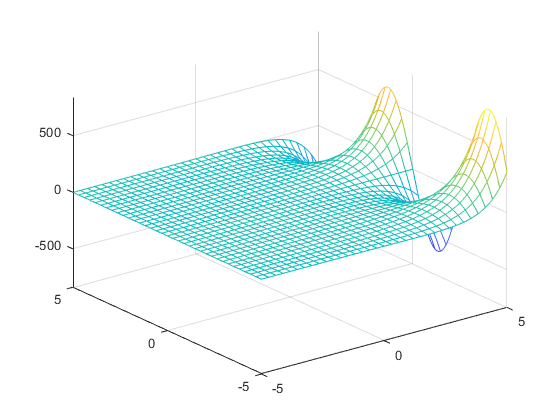

fmesh(U)

% 3)
x0=0;y0=0;
U=simplify(int(P1,x,x0,x)+int(subs(Q1,x,x0),y,y0,y))

$$U = {\mathrm{e}}^{x}\,\left(y\,\cos\left(y\right)-\sin\left(y\right)+x\,\sin\left(y\right)\right)$$

syms C
eq2=U==C

$$eq2 = {\mathrm{e}}^{x}\,\left(y\,\cos\left(y\right)-\sin\left(y\right)+x\,\sin\left(y\right)\right)=C$$